
=== Running Experiment 1 ===


cfg = struct with fields:
    mm: 'sgdm'
    lr: 0.1000
    mb: 256


    mm: 'sgdm'
    lr: 0.1000
    mb: 256




=== Running Training 1 ===

=== Done Training 1 ===


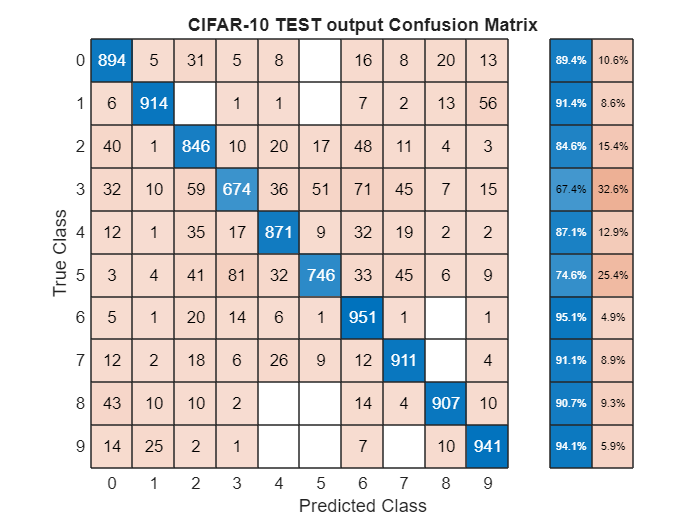

Overall Accuracy (from CM): 86.55%



=== Running Experiment 2 ===


cfg = struct with fields:
    mm: 'adam'
    lr: 1.0000e-03
    mb: 128


    mm: 'adam'
    lr: 1.0000e-03
    mb: 128




=== Running Training 2 ===


clearvars
global options
% Define ranges
configs = [
    struct('mm','sgdm','lr',0.1,'mb',256),...    
    struct('mm','adam','lr',0.001,'mb',128),...
    struct('mm','sgdm','lr',0.01,'mb',64),...
    struct('mm','rmsprop','lr',0.001,'mb',128),...
    struct('mm','sgdm','lr',0.01,'mb',128),...
    struct('mm','rmsprop','lr',0.01,'mb',64),...
    struct('mm','rmsprop','lr',0.001,'mb',256),...
    struct('mm','adam','lr',0.001,'mb',256),...
    struct('mm','sgdm','lr',0.01,'mb',256),...
    ];

loadtrainingdata
co = 5;
for expNum = 1:length(configs)
    fprintf('\n=== Running Experiment %d ===\n', expNum);
    clearvars -except configs co mm  ...
        options expNum ...
        trainImages valImages testImages ...
        trainLabels valLabels testLabels ...
        imageAugmenter trainDS valDS testDS 
    
    cfg = configs(expNum)
    mm = cfg.mm;
    disp(cfg)
    createTrainingOptions(cfg.mm,cfg.lr*cfg.mb/128,30,150,cfg.mb,valDS,floor(size(trainImages,4)/cfg.mb),0.9,true);
    conv5layers
    runfile
end